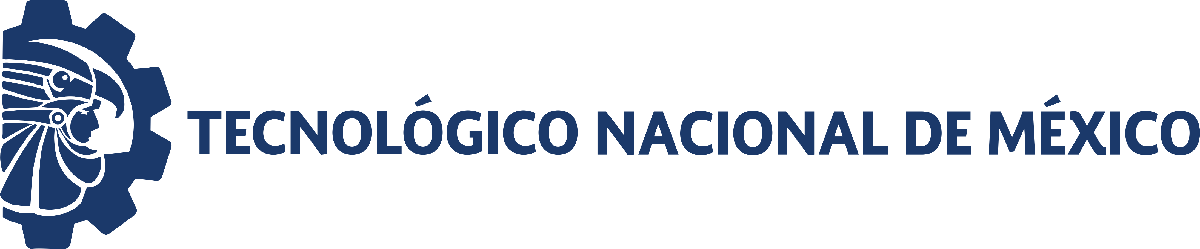                                 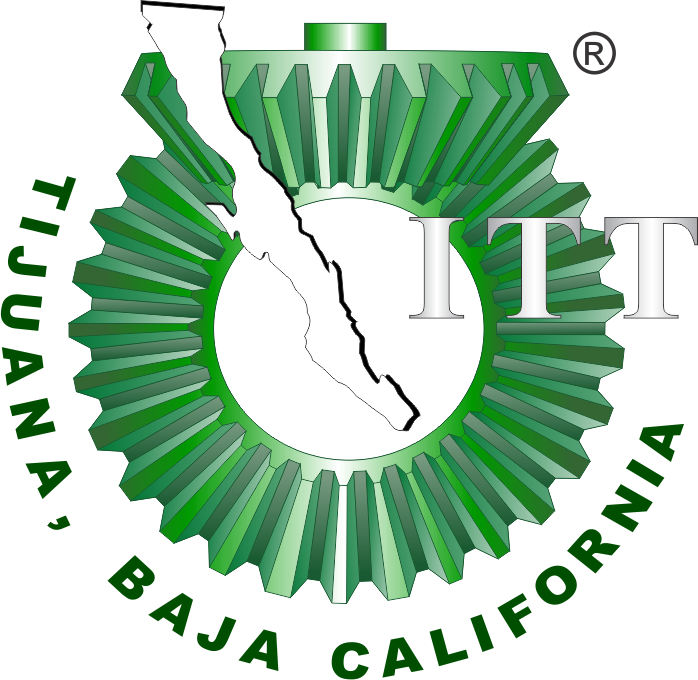

# Proyecto final: Diabetes tipo 2

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

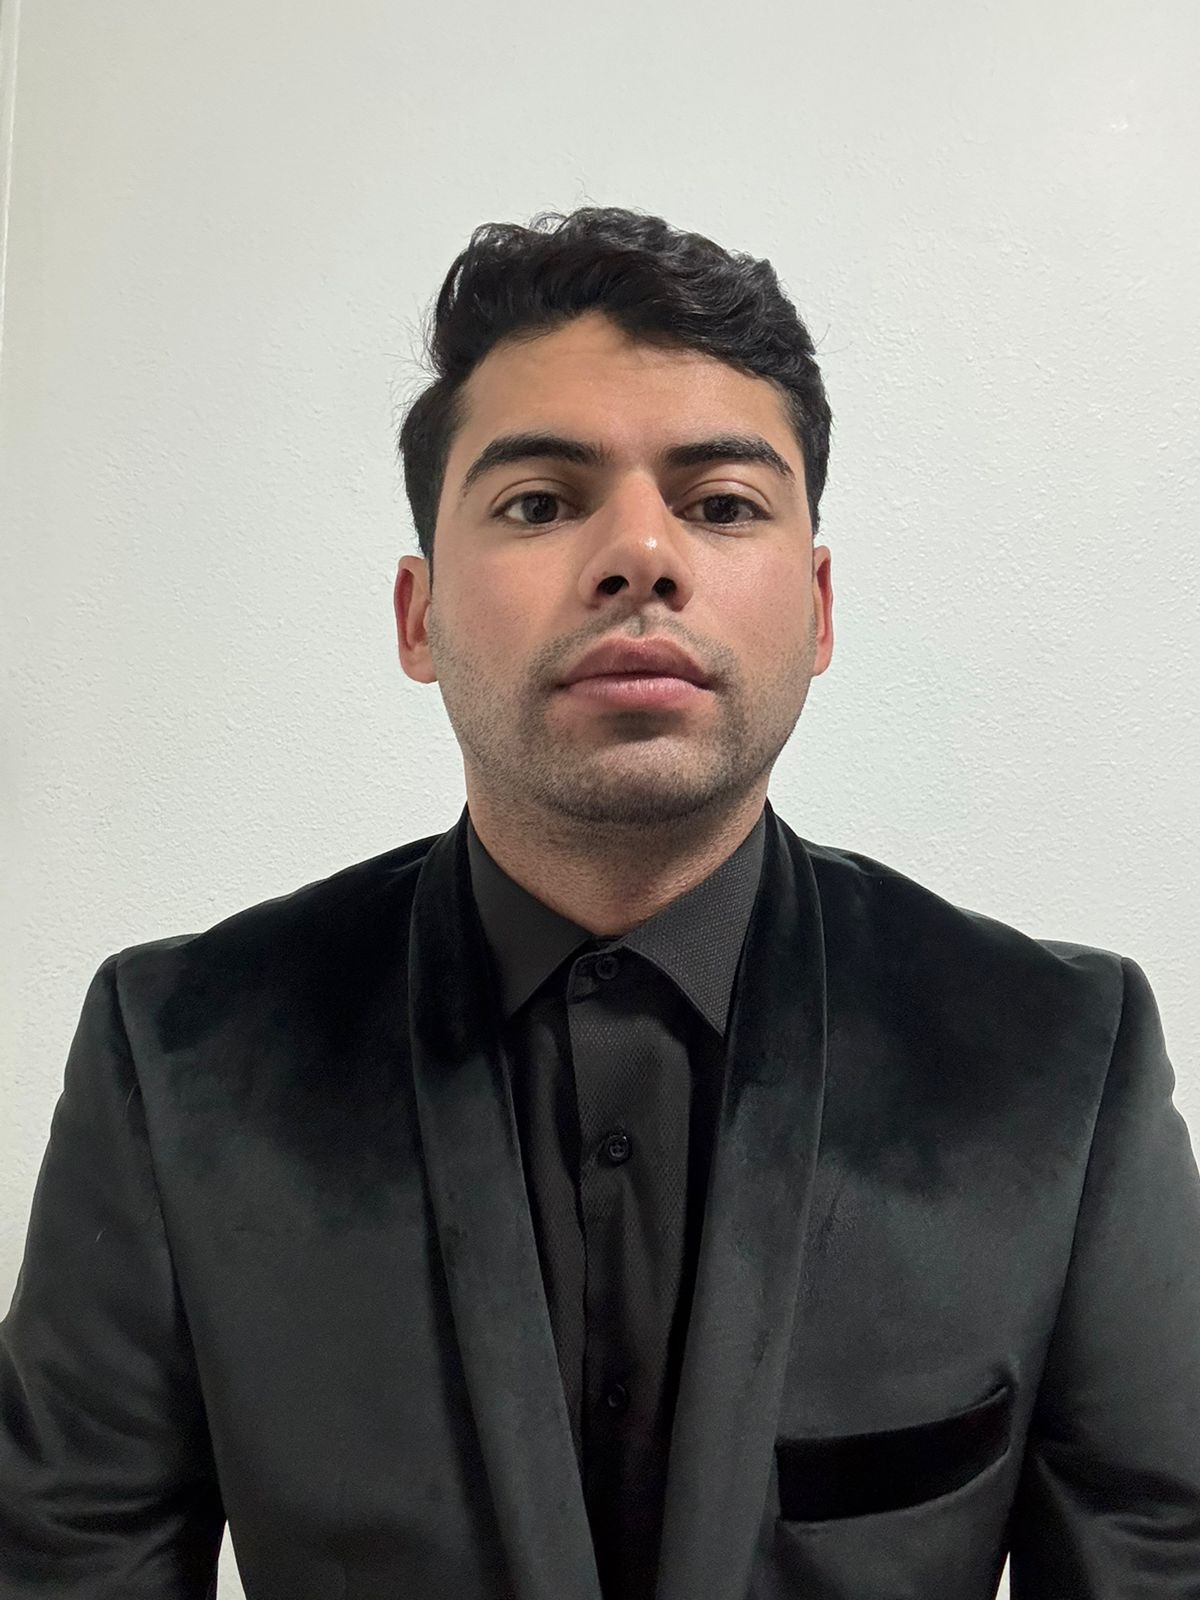

Nombre del alumno: ** Perez Chavez Marco Antonio**

Número de control: **19212423**

Correo institucional: **marco.perez193@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = "10";
parameters.StopTime = tend;
parameters.Solver = "ode15s";
parameters.MaxStep = "1E-3";

## Rendimiento del controlador 

kP = 209.526932103208

kI = 4712.72816525048

kD = 1.13804884347251

## Tratamiento

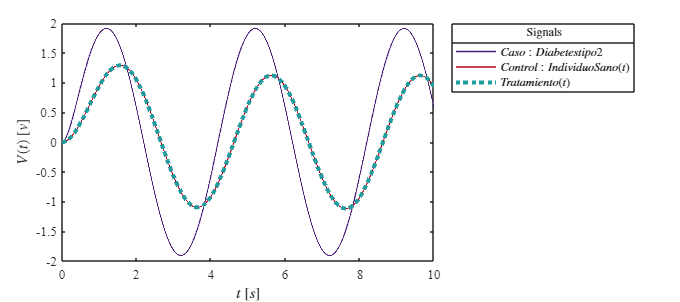

Signal = 'Tratamiento';
file = 'DiabetesLC';
open_system(file);
x = sim(file, parameters);
plotsignals (x.t, x.Ppx, x.Ppy, x.Ppz, Signal)

## Funcion: Respuesta a las señales

function plotsignals(t, Ppx, Ppy, Ppz, Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'Centimeters', 'Position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(10,'points')
    
    naranja = [1, 128/255, 0];
    morado = [76/255, 31/255, 122/255];
    azul = [33/255, 155/255, 157/255];
    rojo = [184/255, 0/255, 31/255];

    hold on; grid off, box on;

    plot (t, Ppx, 'LineWidth', 1, 'Color', morado)
    plot (t, Ppy, 'LineWidth', 1, 'Color', rojo)
    plot (t, Ppz, ':', 'LineWidth', 3, 'Color', azul)

     L = legend('${Caso: Diabetes tipo 2}$','${Control: Individuo Sano}(t)$','${Tratamiento}(t)$');
    set(L,'Interpreter','Latex','FontSize',9,'location','NorthEastOutside')
    title(L,'Signals')

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
    ylabel('$V(t)$ $[v]$', 'Interpreter', 'Latex')
  
    end
    
